%Lab4: Impedanz und Admittanz
format short eng;
clf

%%
disp('Aufgabe 2 - Messung des Blindwiderstandes eines Kondensators mit C = 1 µF');

Aufgabe 2 - Messung des Blindwiderstandes eines Kondensators mit C = 1 µF


**Prognose / Erwartung:** 

Mit  steigender Frequenz 

-> Xc wird kleiner 

-> steigender Strom, da Spannung = const. 



f = [250, 500, 1000];
omega = 2*pi*f;

%gemessene Spannung in V
UC=[2.996 2.998 2.998]

UC =      2.9960e+000     2.9980e+000     2.9980e+000




%Gemessener Strom in mA
IC=[4.728 9.465 18.83]*1e-3

IC =      4.7280e-003     9.4650e-003    18.8300e-003




XC = UC./IC

XC =    633.6717e+000   316.7459e+000   159.2140e+000


C_mess = 1./(omega.*XC)

C_mess =      1.0047e-006     1.0049e-006   999.6289e-009



%Gemessene Kapazität via LCR-Brücke
C_LCR=[0.00000101 9.99e-7 0.000001]

C_LCR =      1.0100e-006   999.0000e-009     1.0000e-006


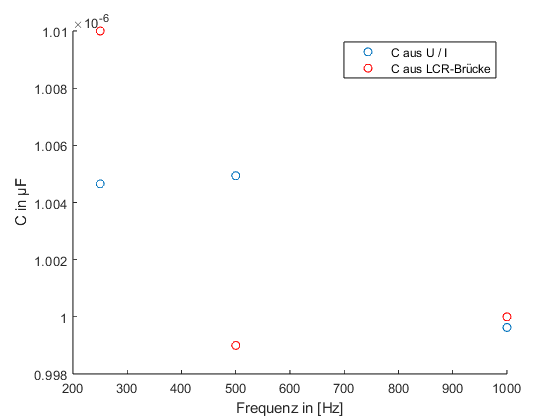


figure(1)
hold on

plot(f,C_mess, 'o')
plot(f,C_LCR, 'ro')
ylabel('C in µF');
xlabel('Frequenz in [Hz]');

legend('C aus U / I ','C aus LCR-Brücke');
hold off

**Auswertung: **

C = const. -> Bauteileigenschaft , evtl. Messabweichungen aufgrund von parasitären Widerstand in C gerade bei höheren Frequenzen, da Xc kleiner wird und Einfluss des parasitären Widerstands steigt.

disp('Aufgabe 3 - Luftspule');

Aufgabe 3 - Luftspule


  **Prognose:** 

????

disp('ILmess = [100 70 40] mA bei [250 500 1000] Hz'); 

ILmess = [100 70 40] mA bei [250 500 1000] Hz




%Mit Multimeter gemessener Widerstand in Ohm
R_Mess = 16.01;

f = [250, 500, 1000];
omega = 2*pi*f;

%gemessene Spannung in V
UL=[2.003 1.999 2]

UL =      2.0030e+000     1.9990e+000     2.0000e+000



%Gemessener Strom in mA
IL=[100.98 69.82 39.84]*1e-3

IL =    100.9800e-003    69.8200e-003    39.8400e-003



ZL = UL./IL

ZL =     19.8356e+000    28.6308e+000    50.2008e+000



XL=sqrt(ZL.^2-R_Mess^2)

XL =     11.7103e+000    23.7361e+000    47.5794e+000



L_mess = XL./omega

L_mess =      7.4550e-003     7.5554e-003     7.5725e-003



%Gemessene Induktivität via LCR-Brücke in mH
L_LCR=[7.45 7.554 7.5879    ]*1e-3

L_LCR =      7.4500e-003     7.5540e-003     7.5879e-003


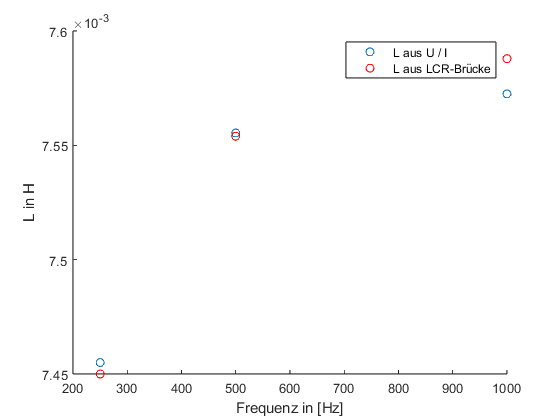


figure(2)
clf
hold on

plot(f,L_mess, 'o')
plot(f,L_LCR, 'ro')
ylabel('L in H');
xlabel('Frequenz in [Hz]');

legend('L aus U / I ','L aus LCR-Brücke');

**Auswertung: **

1) L **sollte** konstant bleiben, 

mit sinkender Frequenz nimmt X_L aber ab und der Einfluss von R_L steigt 

-> Verluste durch e.g. Wirbelströme, Skin-Effekt, ...

2) Vergleich zu Messungen mit LCR-Brücke:

????

%%
disp('Aufgabe 4 - Spule mit Kern bei 715 mH / 2400 Ohm');

Aufgabe 4 - Spule mit Kern bei 715 mH / 2400 Ohm


**Prognose: **

??????

%Mit Multimeter gemessener Widerstand in Ohm
R_MessEK = 16.01;

f = [1000];
omega = 2*pi*f;

%gemessene Spannung in V
ULEK=1.999

ULEK =      1.9990e+000



%Gemessener Strom in mA
ILEK=0.231*1e-3

ILEK =    231.0000e-006



ZLEK = ULEK./ILEK

ZLEK =      8.6537e+003



XLEK=sqrt(ZLEK.^2-R_MessEK^2)

XLEK =      8.6537e+003



L_messEK = XLEK./omega

L_messEK =      1.3773e+000



mu_EK= L_messEK / mean(L_mess)

mu_EK =    182.9621e+000


**Auswertung:**

?????

%%
disp('Aufgabe 5 - Drei-Spannungsmessermethode bei R = 28 Ohm bei 500 Hz');

Aufgabe 5 - Drei-Spannungsmessermethode bei R = 28 Ohm bei 500 Hz


**Prognose:**

??????

f = 500;
omega = 2*pi*f;
disp('gemessene Werte sind hier einzutragen:');

gemessene Werte sind hier einzutragen:


UGen = 3.62

UGen =      3.6200e+000


UZ = 2.05

UZ =      2.0500e+000


UR = 2.05

UR =      2.0500e+000


R_var= 30

R_var =     30.0000e+000


phi_mess = 28.5

phi_mess =     28.5000e+000



phi_th=acos(UGen/(2*UR))*360/(2*pi)

phi_th =     28.0025e+000


Theorie:

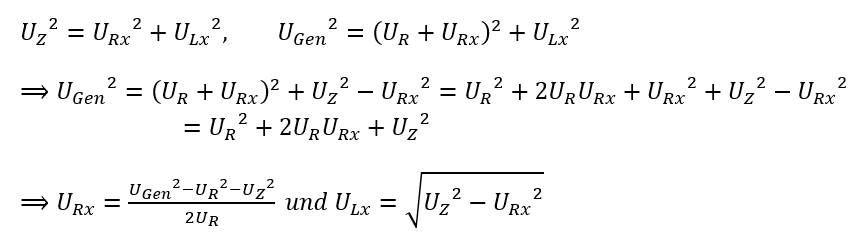


URx = (UGen^2 - UR^2 - UZ^2) / (2*UR)

URx =      1.1462e+000


ULx = sqrt(UZ^2 - URx^2) 

ULx =      1.6996e+000


I = UR / R_var

I =     68.3333e-003



Rx = URx / I

Rx =     16.7736e+000


XL = ULx / I

XL =     24.8726e+000


Lx = XL/omega

Lx =      7.9172e-003


**Auswertung:**

???

disp('Aufgabe 6 - Blindstromkompensation bei 500 Hz');

Aufgabe 6 - Blindstromkompensation bei 500 Hz


**Prognose**:

??????

  omega=2*pi*500;
 Ugen = [3 3 3 3 3 3 3 3 3 3 3 ];
C_var = [0 0.1 0.2 0.3 0.4 0.5 0.6 0.7 0.8 0.9 1 ]*1e-6 %´microFarad

C_var =      0.0000e+000   100.0000e-009   200.0000e-009   300.0000e-009   400.0000e-009   500.0000e-009   600.0000e-009   700.0000e-009   800.0000e-009   900.0000e-009     1.0000e-006


Imess = [3.216 2.417 1.761 1.456 1.705 2.336 3.124 3.977 4.86 5.754 6.731 ]*10^-3 %miliAmpere;

Imess =      3.2160e-003     2.4170e-003     1.7610e-003     1.4560e-003     1.7050e-003     2.3360e-003     3.1240e-003     3.9770e-003     4.8600e-003     5.7540e-003     6.7310e-003


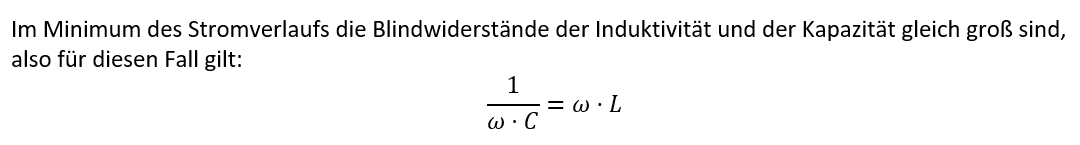

Cmin=0.3*10^-6;
Ugen_min=3;
Imess_min=1.456*10^-3;

L_Comp = 1/(omega^2*Cmin)

L_Comp =    337.7373e-003


R_Comp = Ugen_min/(Imess_min)

R_Comp =      2.0604e+003


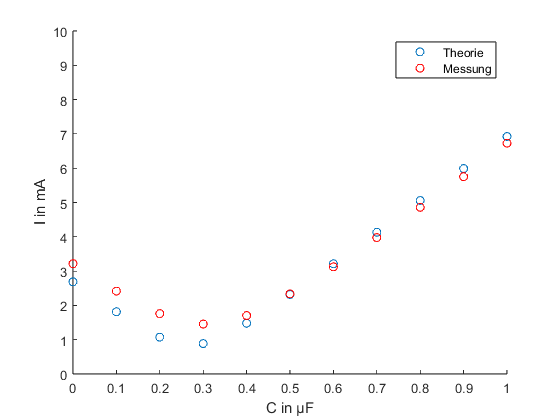


L_LCR=337.44*1e-3;
R_LCR=350;


ZL = R_LCR+j*omega*L_LCR;
%ZL = R_Comp+j*omega*L_Comp

ZC = 1./(j*omega*C_var);
Zges = 1./(1/ZL + 1./ZC);
Zgesabs = abs(Zges);
Irech = Ugen./Zgesabs;


figure(3)
hold on
plot(C*1e6, Irech*1e3, 'o');
plot(C*1e6, Imess*1e3, 'or');

xlabel('C in µF');
ylabel('I in mA');
axis([0 1 0 10])
legend('Theorie','Messung');

**Auswertung:**

??????